# Task 2 

## Team members:

- Isabelle Willing

- Daniel Murrieta-Alvarez

- Sreenivasa Goutham Malepati

with the transfer function and the values the first step is to calculate the matrices A, B, C and B, lets begining by constructing the transfer function model:

clear
close all
%% Constants of the system
R=5000;
L=0.5;
Cap=5e-9;
%% TF model
num = [0 0 1];
den = [L*Cap R*Cap 1];
tfsys = tf(1,[L*Cap R*Cap 1])

tfsys =
 
               1
  ---------------------------
  2.5e-09 s^2 + 2.5e-05 s + 1
 
Continuous-time transfer function.



The TF with the respective values is shown above, a brief analysis:

n_ord = order(tfsys);
damp(tfsys)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.00e+03 + 1.94e+04i     2.50e-01       2.00e+04         2.00e-04    
 -5.00e+03 - 1.94e+04i     2.50e-01       2.00e+04         2.00e-04    


Shows the order of the system is 2, and an overdamped characteristic. The command wiil be tf2ss willl be used, then the new state space system willl be constructed:

%% Space state model
[A,B,C,D] = tf2ss([0 0 1],[L*Cap R*Cap 1]);
sssys=ss(A,B,C,D)

sssys =
 
  A = 
           x1      x2
   x1  -1e+04  -4e+08
   x2       1       0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
          x1     x2
   y1      0  4e+08
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Set the initial conditions and the allocate the variables...shalala

## Initial conditions

V_capacitor = 6;                        %%Initial voltage in the capacitor
Q_capacitor = Cap * V_capacitor;          
xuno0 = 0;%-0.0005;                     %initial conditions x1
xdos0 =Q_capacitor;%0.000000005;        %initial conditions x2

%% Vectors
h=0.00001;                      % Step size
t_initial=0;                    % Initial time
t_final=0.0015;                 % Final time
t=t_initial:h:t_final-h;        % Simulation time         
x=zeros(n_ord,numel(t));        % Allocate X
y = zeros(size(t));             % Allocate Y
x(1,1)=xuno0;                   % Assign initial conditions
x(2,1)=xdos0;                   % Assign initial conditions
ustep=ones(size(t));            % Step input
u_fsw=chirp(t,deg2rad(500),0.001,deg2rad(400000));% Freq sweep input

The algorithm to solve the system 

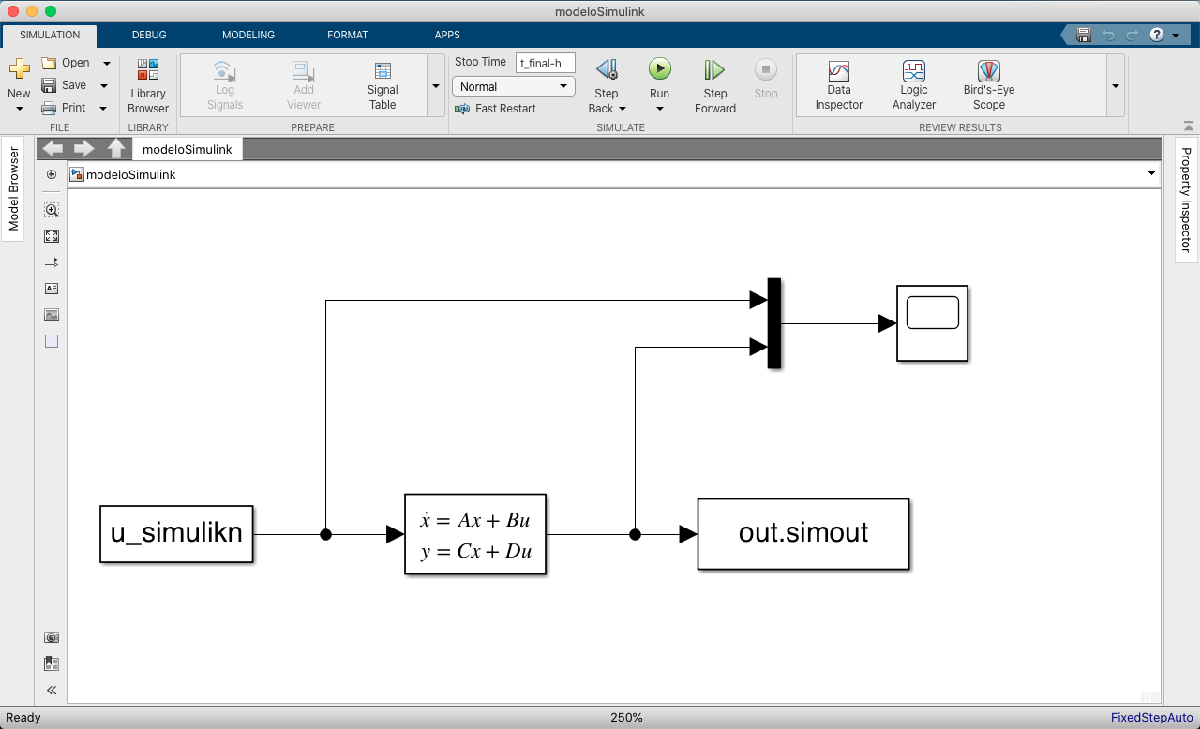

%% Simulations!
u=ustep;                                            %% Step Input    
[ys xs] =  MyRungeKutta_IDG (x,y,u,t,h,A,B,C,D);    %% Using our function
u_simulikn=[t' u'];                                 %% Simulink compatib.
StepSimulink=sim('modeloSimulink');                 %% Simulink simulation

u=u_fsw;                                            %% Freq sweep Input    
[yc xc] =  MyRungeKutta_IDG (x,y,u,t,h,A,B,C,D);    %% Using our function
u_simulikn=[t' u'];                                 %% Simulink compatib.
ChirpSimulink=sim('modeloSimulink');                %% Simulink simulation


Now lets calculate how close both responses are, first analyzing if they are identical, the calculatinf the absolute value of their response: 

%% Discussion
% %Are output vectors equal? 
if(isequal(ys,StepSimulink.simout))
    disp('Identical output vectors')
else
     disp('Non Identical output vectors')
end

Non Identical output vectors



for i=1:numel(ys)                                 %Calculate diff
    difs(i) = abs(ys(i)-StepSimulink.simout(i));
end

                                                  %Are output vectors equal?
if(isequal(yc,ChirpSimulink.simout))
    disp('Identical output vectors')
else
     disp('Non Identical output vectors')
end

Non Identical output vectors


for i=1:numel(yc)                               %Calculate diff
    difc(i) = abs(yc(i)-ChirpSimulink.simout(i));
end

Plot all togheter....

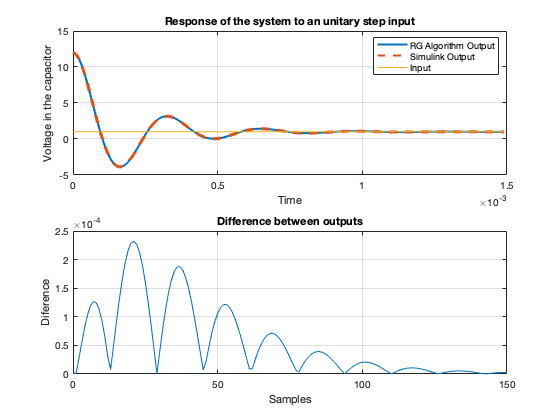

%% Plotting
  figure
    subplot(2,1,1)%%%%%
    plot(t,ys,'LineWidth',2)
    title('Response of the system to an unitary step input')
    hold on
    plot(StepSimulink.tout,StepSimulink.simout,'--','LineWidth',2)
    plot(t,ustep)
    legend('RG Algorithm Output ','Simulink Output','Input')
    xlabel('Time')
    ylabel('Voltage in the capacitor')
    grid on
    hold off
    subplot(2,1,2)%%%%%
    plot(difs)
    title('Difference between outputs')
    xlabel('Samples')
    ylabel('Diference')
    grid

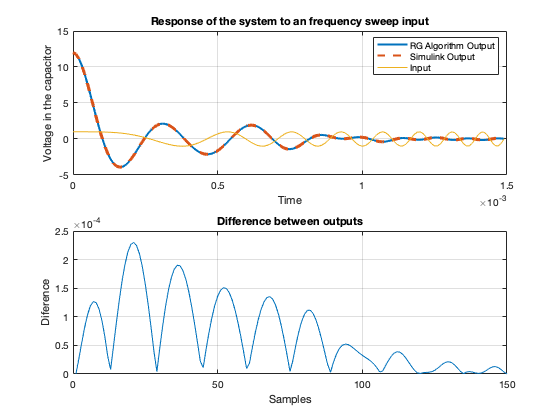

    
    figure
    subplot(2,1,1)%%%%%
    plot(t,yc,'LineWidth',2)
    title('Response of the system to an frequency sweep input')
    hold on
    plot(ChirpSimulink.tout,ChirpSimulink.simout,'--','LineWidth',2)
    plot(t,u_fsw)
    legend('RG Algorithm Output ','Simulink Output','Input')
    xlabel('Time')
    ylabel('Voltage in the capacitor')
    grid on
    hold off
    subplot(2,1,2)%%%%%
    plot(difc)
    title('Difference between outputs')
    xlabel('Samples')
    ylabel('Diference')
    grid

Now a short description of the Runge-Kutta algorith will be presented:

  
%% Functions defs

function [y x] = MyRungeKutta_IDG (x,y,u,t,h,A,B,C,D);
% Main Runge-Kutta cycle
            %%Iterate thru the inputs, step and then freq sweep
   
    y(1) = C*x(:,1) + D*u(1);    % Assign initial conditions to Y
    
    for i = 1:numel(t)-1        %% Main cycle: calculate everything

             Xtemp = [x(1,i);x(2,i)];
             k1x1 = h * dotx(1,Xtemp,u(i),A,B);
             k1x2 = h * dotx(2,Xtemp,u(i),A,B);

            Xtemp = [x(1,i)+(k1x1/2) ; x(2,i)+(k1x2/2)];
            k2x1 = h * dotx(1,Xtemp, u(i),A,B );
            k2x2 = h * dotx(2,Xtemp, u(i),A,B );
           
             Xtemp = [x(1,i)+(k2x1/2) ; x(2,i)+(k2x2/2)];
            k3x1 = h * dotx(1,Xtemp, u(i),A,B );
            k3x2 = h * dotx(2,Xtemp, u(i),A,B );
            
             Xtemp = [ x(1,i) + k3x1 ; x(2,i) + k3x2 ];    
            k4x1 = h * dotx(1,Xtemp, u(i),A,B );
            k4x2 = h * dotx(2,Xtemp, u(i),A,B );
           
            x(1,i+1) = x(1,i) + ( k1x1 + (k2x1*2) + (k3x1*2) + k4x1)/6.0; % Calculate state variable 1
            x(2,i+1) = x(2,i) + ( k1x2 + (k2x2*2) + (k3x2*2) + k4x2)/6.0; % Calculate state variable 2
            y(i+1) = C*x(:,i+1) + D*u(i+1);          
    end  
end   
%%
function dxdt = dotx(n,X,ui,A,B) %Receives: Number of state variable
                                  %          Current value of X, column*
                                  %          Current value of u
                                  %          State matrix A
                                  %          Input matrix B
    dxdt= A(n,:)*X + B(n)*ui;

end